# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

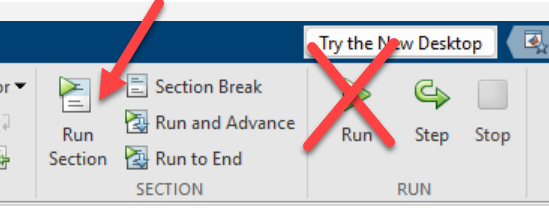

Before you start with the exercises, let's add the folder with the files and solutions required to complete each step.

close all;
clear all;
bdclose all;
clc;

addpath('./Solutions')
addpath('./Files')

## Exercise 4: Integrate a crossed polarized dipole antenna and a Wilkinson combiner

Number of steps: 3

Expected completion time: 20 minutes

In this section you design a dipole crossed antenna and a Wilkinson combiner to merge the two polarization components of the incoming signal. Notice that the feed network of the antenna must implement a 90 degrees relative phase shift. The antenna and the Wilkinson combiner are integrated in the RF receiver.

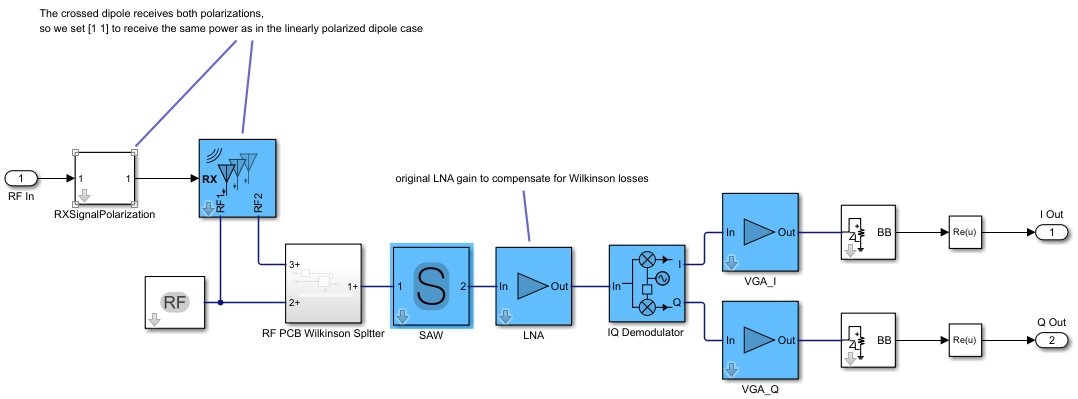

**4.1** **Design the **`dipoleCrossed` catalog element from from Antenna Toolbox to operate at the desired center frequency. Visualize the far field radiation pattern and the S-parameters.

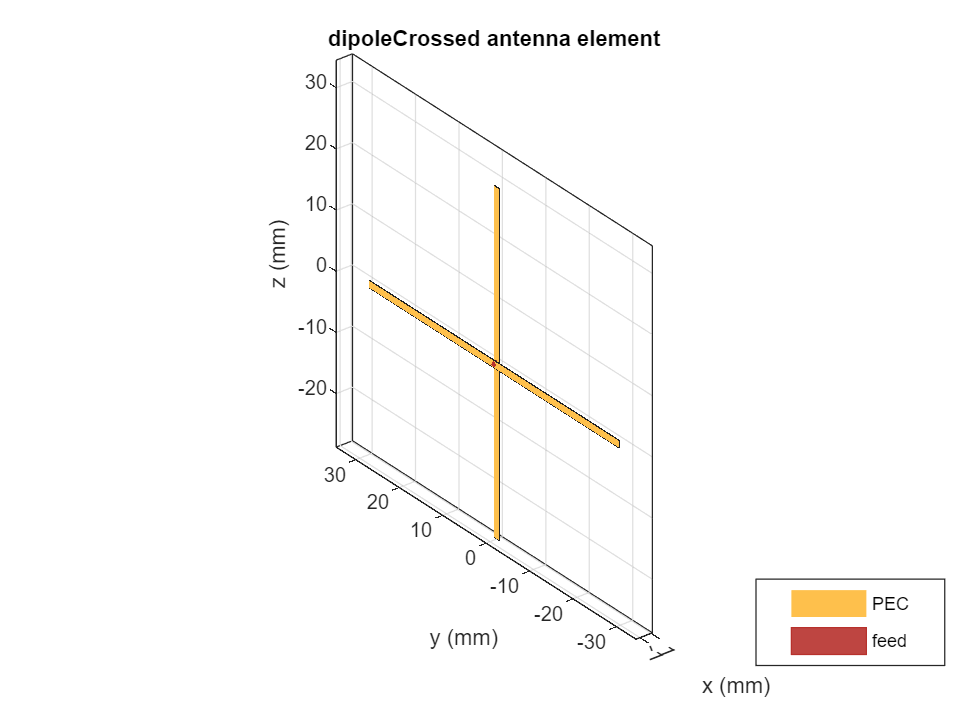

Xdipole = design(dipoleCrossed, 2.45e9);
Xdipole.Tilt = 45;
figure; show(Xdipole);

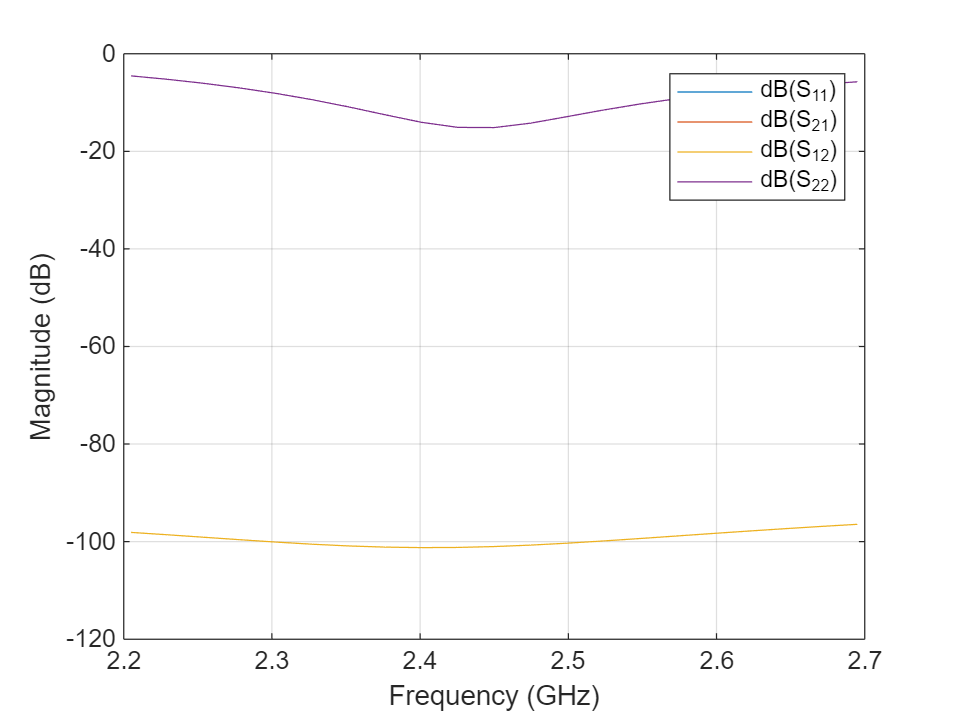

figure; pattern(Xdipole,2.45e9);
sparamXdipole = sparameters(Xdipole, (2205:24.5:2695)*1e6);
figure; rfplot(sparamXdipole);

**4.2** **Design the **`wilkinsonSplitter` catalog element from RF PCB Toolbox to operate at the desired center frequency. Analyze the S-parameters and save them as a Touchstone file. The Wilkinson splitter in this receiver will be used as a signal combiner.

wilkCombiner=design(wilkinsonSplitter, 2.45e9);
show(wilkCombiner);
sparamWilkinson=sparameters(wilkCombiner, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkinson);
rfwrite(sparamWilkinson,'wilkinsonSplitterSparams.s3p')

**4.3** Open the Simulink **testbench **`Exercise3_RFReceiverWithXdipole` and verify the ChER.

open_system('Exercise3_RFReceiverWithXdipole.slx')

Although we use a dual polarized antenna, because the signals are not correctly combined the ChER will be very high ~50%!

In order to properly combine the signals at the 2 antenna ports you need to include a 90 degrees phase shift on one of the combiner branches. 

*Implement the correct phase shift and verify the ChER. *

With the correct phase shift the ChER will be ~11%.

*What is the cause for the ChER degradation compared to the initial simulation when the ChER was around 7%?*

**Solution **

Open the model where the dipole crossed antenna and the Wilkinson combiner have been integrated together with a behavioral model of the phase shifter:

open_system('Solution3_RFReceiverWithXdipole.slx')

The additional insertion loss of the Wilkinson combiner contributes to additional noise and degrades the available SNR. 

Extra: you can verify the updated budget including the losses of the Wilkinson combiner. For this, you need to identify the respective 2 port S-parameters of the combiner. Notice that the SNR is now reduced compared to the original budget and the total noise figure exceeds 14 dB.

rfwrite(snp2smp(sparamWilkinson,[1 2]),'wilkinson2ports.s2p')
rfBudgetAnalyzer('rfbudget_RFReceiverXdipole.mat') 

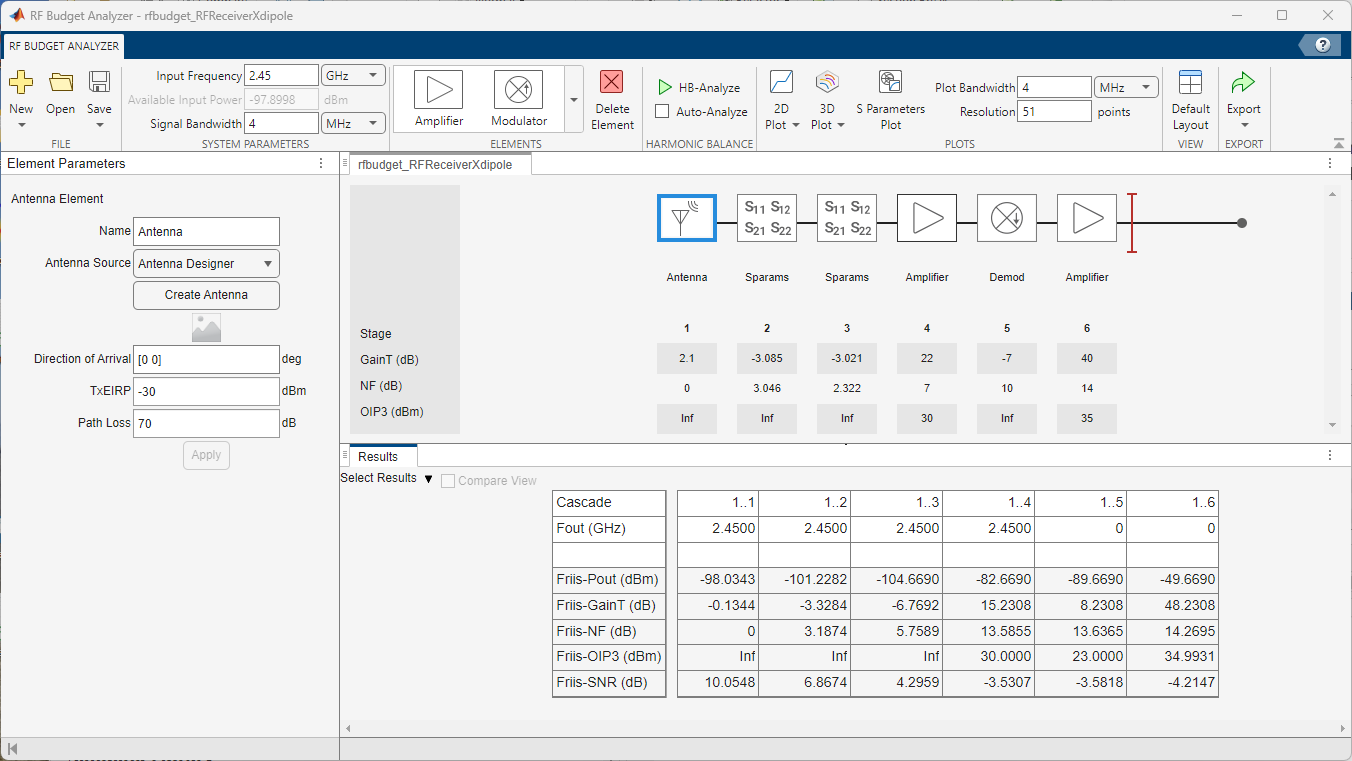

**Exercise outcome and summary**

In this exercise, you learned how to integrate an antenna with mulitple feeds into your testbench.